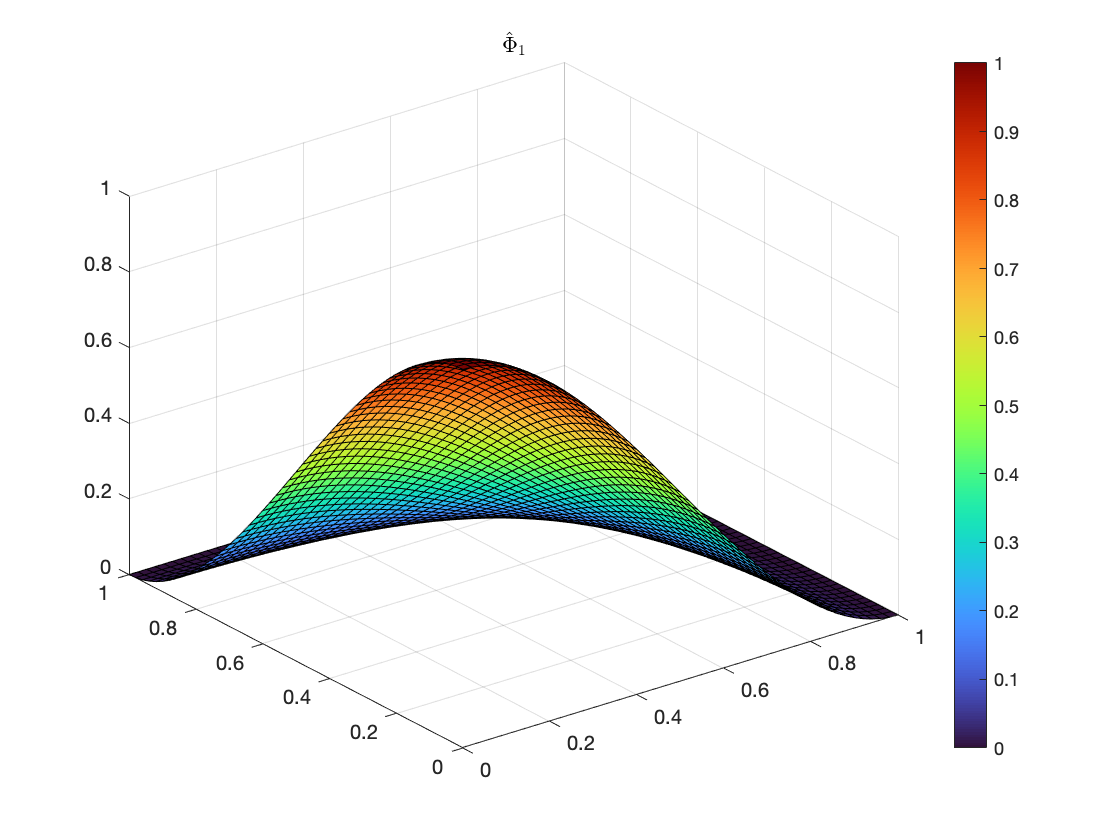

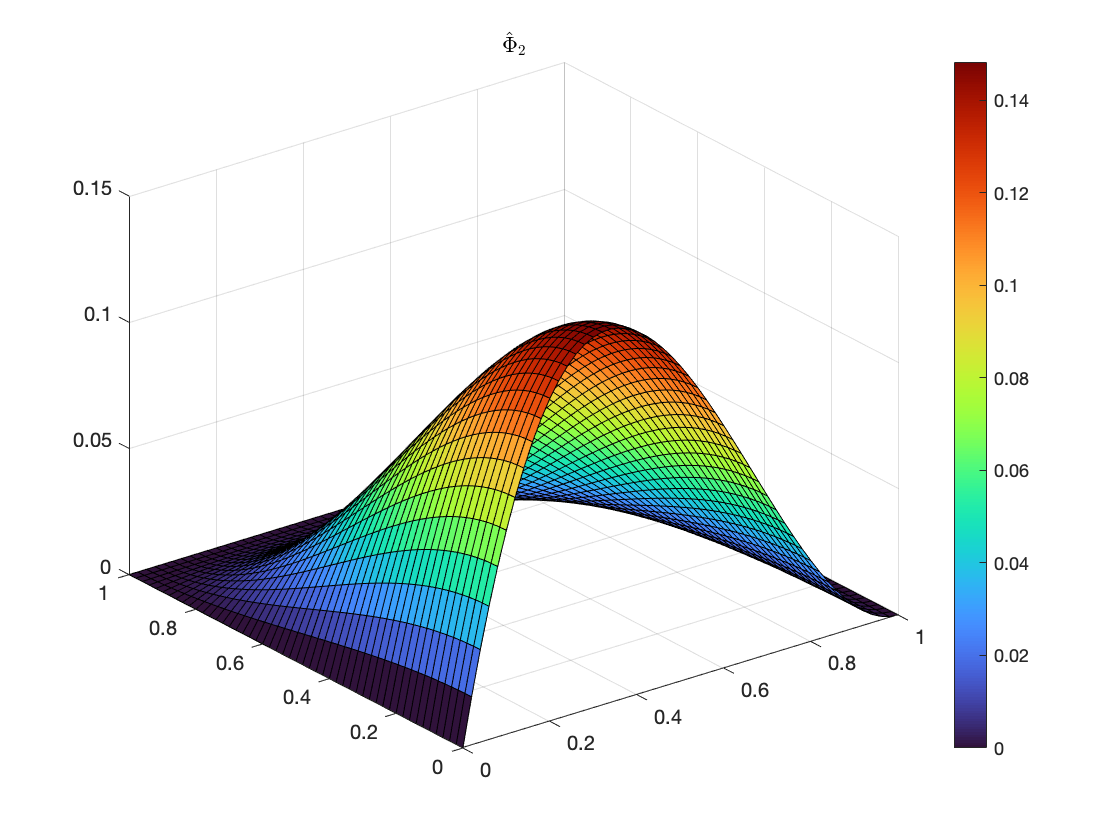

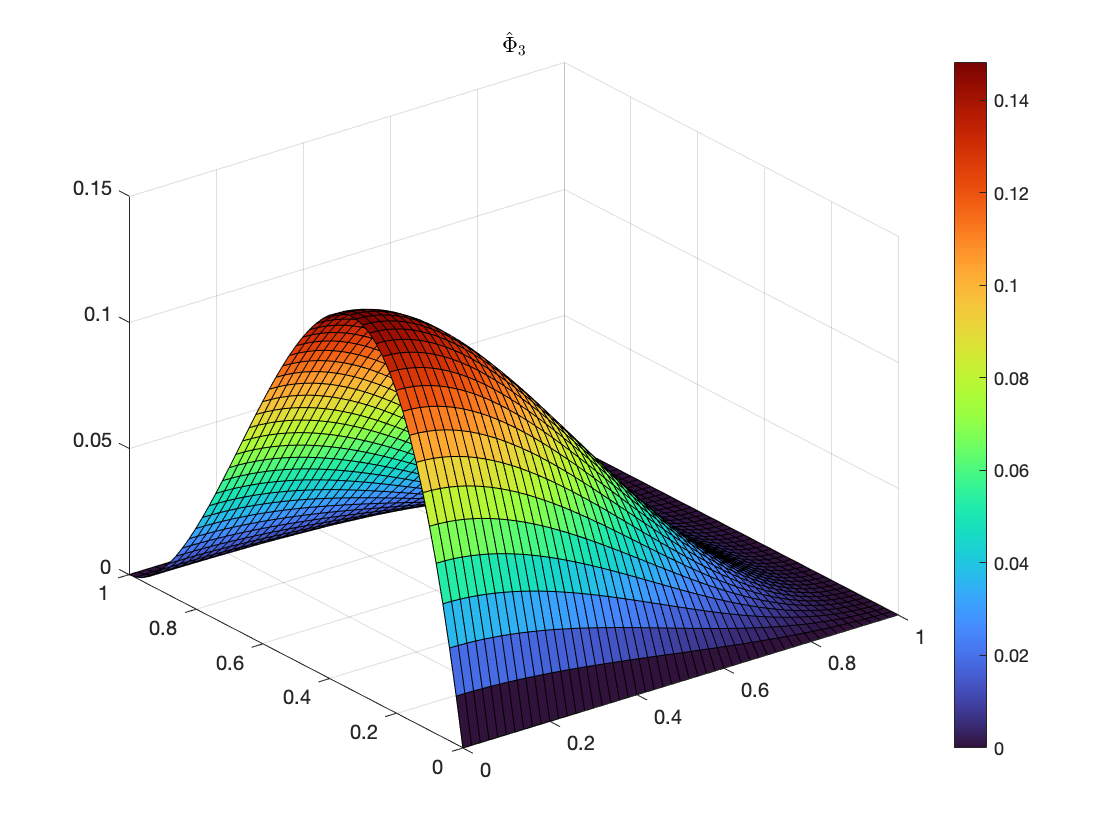

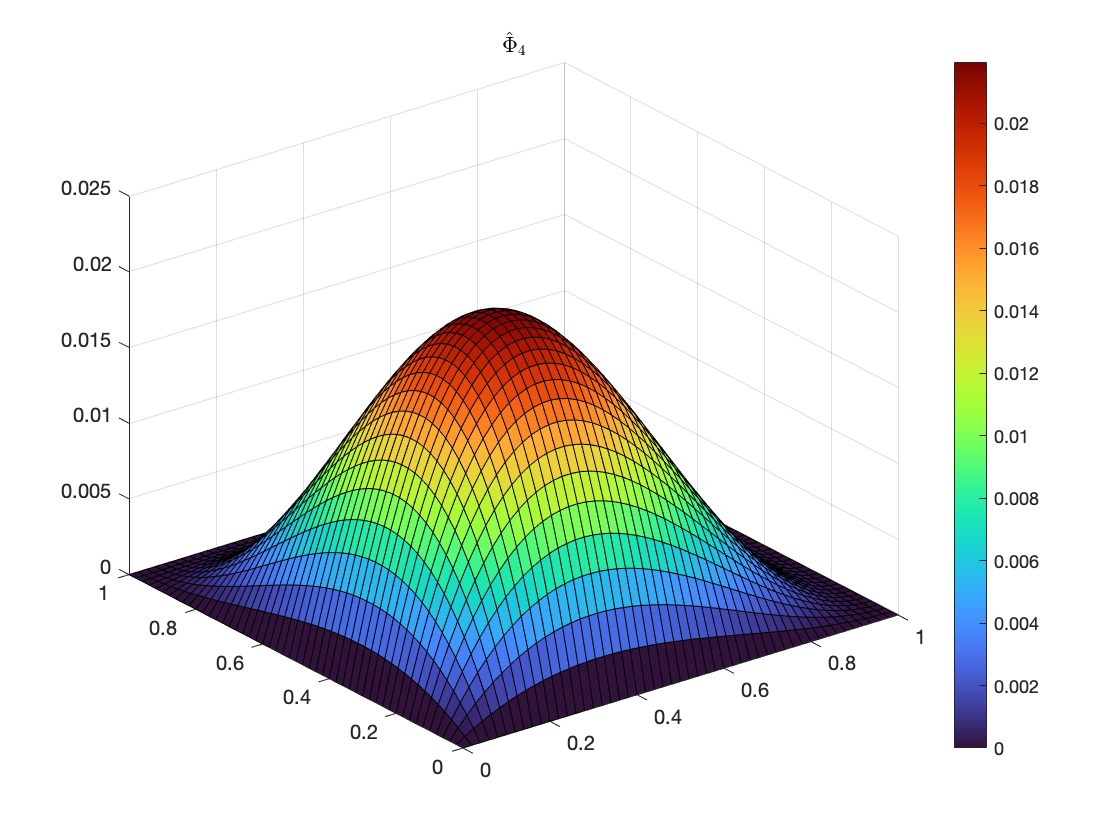

hx = 2e-2;
hy = hx;
xs = 0:hx:1;
ys = 0:hy:1;
Z = zeros(length(xs), length(ys));
[X,Y] = meshgrid(xs, ys);
for n=1:4
    for i=1:length(xs)
        for j=1:length(ys)
            x = xs(i); y = ys(j);
            Z(i,j) = h2d(x, y, n);
        end
    end
    figure
    surf(X,Y,Z)
    title(sprintf('$\\hat \\Phi_{%i}$',n), 'Interpreter',"latex")
    colormap turbo
    colorbar
%     view([0 90])
end

% 1d
Kel1d = zeros(4,4);
for i=1:4
    for j=1:4
        func = @(x) d2_h1d(x,i)*d2_h1d(x,j);
        Kel1d(i,j) = gauss1d(func);
    end
end

% 2d
Kel2d = zeros(16,16);
for i=1:16
    for j=1:16
        func = @(x,y) d2_h2d(x, y, i)*d2_h2d(x, y, j);
        Kel2d(i,j) = gauss2d(func);
    end
end

Kel1d

Kel1d =     12     6   -12     6
     6     4    -6     2
   -12    -6    12    -6
     6     2    -6     4


Kel2d

Kel2d =    11.7943    4.2971    4.2971    0.8486   -5.7943    2.0971   -1.2971    0.2486   -0.2057    0.9029    0.9029   -0.3514   -5.7943   -1.2971    2.0971    0.2486
    4.2971    1.9200    1.8486    0.4267   -2.0971    0.5771   -0.2486    0.0219   -0.9029    0.4229    0.3514   -0.1114   -1.2971    0.0800    0.2486   -0.0400
    4.2971    1.8486    1.9200    0.4267   -1.2971    0.2486    0.0800   -0.0400   -0.9029    0.3514    0.4229   -0.1114   -2.0971   -0.2486    0.5771    0.0219
    0.8486    0.4267    0.4267    0.1117   -0.2486    0.0219    0.0400   -0.0184   -0.3514    0.1114    0.1114   -0.0263   -0.2486    0.0400    0.0219   -0.0184
   -5.7943   -2.0971   -1.2971   -0.2486   11.7943   -4.2971    4.2971   -0.8486   -5.7943    1.2971    2.0971   -0.2486   -0.2057   -0.9029    0.9029    0.3514
    2.0971    0.5771    0.2486    0.0219   -4.2971    1.9200   -1.8486    0.4267    1.2971    0.0800   -0.2486   -0.0400    0.9029    0.4229   -0.3514   -0.1114
   -1.2971   -0.2486    0.

save('master_stiff_1d.mat', 'Kel1d');
save('master_stiff_2d.mat', 'Kel2d');

function res = h1d(x,i)
    if i==1
        res = 2*x^3 - 3*x^2 + 1;
    elseif i==2
        res = x^3 - 2*x^2 + x;
    elseif i==3
        res = -2*x^3 + 3*x^2;
    elseif i==4
        res = x^3 - x^2;
    end
end

function res = d2_h1d(x,i)
    if i==1
        res = 12*x - 6;
    elseif i==2
        res = 6*x - 4;
    elseif i==3
        res = -12*x + 6;
    elseif i==4
        res = 6*x - 2;
    end
end

function [i,j] = ind(n)
    index_map = [1 1; 1 2; 2 1; 2 2; 1 3; 1 4; 2 3; 2 4; 3 3; 3 4; 4 3; 4 4; 3 1; 3 2; 4 1; 4 2];
    i = index_map(n,1);
    j = index_map(n,2);
end

function res = h2d(x,y,n)
    [i,j] = ind(n);
    res = h1d(x,i)*h1d(y,j);
end

function res = d2_h2d(x,y,n)
    [i,j] = ind(n);
    res = d2_h1d(x,i)*h1d(y,j) + h1d(x,i)*d2_h1d(y,j);
end

function res = gauss1d(func)
    n=4;
    sqrtm = sqrt(3./7 - 2./7*sqrt(6./5));
    sqrtp = sqrt(3./7 + 2./7*sqrt(6./5));
    ps = [-sqrtm; sqrtm; -sqrtp; sqrtp];
    ws = [(18+sqrt(30))/36; (18+sqrt(30))/36; (18-sqrt(30))/36; (18-sqrt(30))/36];
    res = 0.0;
    for i=1:n
        xi = ps(i);
        w = ws(i);
        res = res+0.5*w*func(0.5*xi + 0.5);
    end
end

function res = gauss2d(func)
    n=4;
    sqrtm = sqrt(3./7 - 2./7*sqrt(6./5));
    sqrtp = sqrt(3./7 + 2./7*sqrt(6./5));
    ps = [-sqrtm; sqrtm; -sqrtp; sqrtp];
    ws = [(18+sqrt(30))/36; (18+sqrt(30))/36; (18-sqrt(30))/36; (18-sqrt(30))/36];
    res = 0.0;
    for i=1:n
        for j=1:n
            xi = ps(i); eta = ps(j);
            w = ws(i)*ws(j);
            res = res+0.5^2*w*func(0.5*xi + 0.5, 0.5*eta + 0.5);
        end
    end
end